# **Practice 2  **

# **Mathematical model of electromechanical device**

                                                                                    **Name: Zhu Chenhao**

                                                                                    **HDU ID: 22320630**

                                                                                    **ITMO ID: 375462**

**Variant : 2**

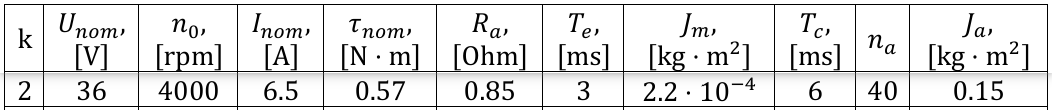

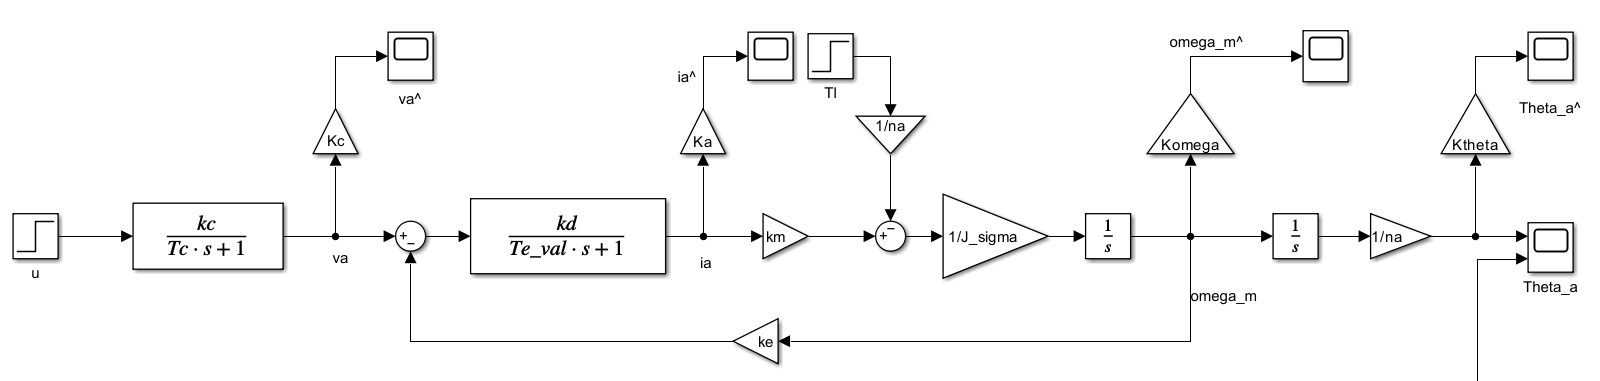

## 1. calculate all parameters of full EMD model and its simplified version.


% 清除工作区
clear all;
close all;
clc;

% 创建新模型
model_name = 'prac2s2022a.slx';

%% 选择k值，变体
k = 2

k = 2

Tmdl = 0.5;

V_max = 10;
% 创建表1的数据（k=0到9）
table1_data = {
    % k  U_nom n0    I_nom tau_nom Ra    Te_val Jm          Tc     na  Ja
    0,  27,   600,  1.4,  0.6,    6.6,  6e-3,  1.5e-3,     4e-3,  15, 0.05;
    1,  48,   1000, 12,   5.5,    0.75, 5e-3,  1.6e-3,     6e-3,  16, 2.75;
    2,  36,   4000, 6.5,  0.57,   0.85, 3e-3,  2.2e-4,     6e-3,  40, 0.15;
    3,  27,   970,  3.76, 1,      1.5,  6e-3,  0.001,      8e-3,  16, 0.84;
    4,  120,  6000, 21,   4,      0.53, 8e-3,  1.9e-3,     8e-3,  40, 5.75;
    5,  27,   2500, 0.92, 0.12,   16.6, 7e-3,  7e-5,       4e-3,  50, 0.01;
    6,  52,   1240, 18,   7.21,   0.3,  10e-3, 0.004,      10e-3, 20, 2.48;
    7,  110,  2400, 11.5, 5,      0.95, 7e-3,  2e-3,       8e-3,  20, 3.7;
    8,  27,   2440, 0.38, 0.04,   32,   6e-3,  5.5e-6,     3e-3,  40, 0.03;
    9,  65,   2000, 14.7, 4.6,    0.65, 10e-3, 3.4e-3,     8e-3,  20, 2.25;
};

% 转换为表格方便查看
varNames = {'k','U_nom','n0','I_nom','tau_nom','Ra','Te_val','Jm','Tc','na','Ja'};
table1 = cell2table(table1_data, 'VariableNames', varNames);
disp(table1);

    k    U_nom     n0     I_nom    tau_nom     Ra     Te_val      Jm        Tc      na     Ja 
    _    _____    ____    _____    _______    ____    ______    _______    _____    __    ____

    0      27      600     1.4       0.6       6.6    0.006      0.0015    0.004    15    0.05
    1      48     1000      12       5.5      0.75    0.005      0.0016    0.006    16    2.75
    2      36     4000     6.5      0.57      0.85    0.003     0.00022    0.006    40    0.15
    3      27      970    3.76         1       1.5    0.006       0.001    0.008    16    0.84
    4     120     6000      21         4      0.53    0.008      0.0019    0.008    40    5.75
    5      27     2500    0.92      0.12      16.6    0.007       7e-05    0.004    50    0.01
    6      52     1240      18      7.21       0.3     0.01       0.004     0.01    20    2.48
    7     110     2400    11.5         5      0.95    0.007       0.002    0.008    20     3.7
    8      27     2440    0.38      0.04        3


% 转换为数值矩阵方便索引
param_matrix = cell2mat(table1_data);


row_idx = k + 1;  % 因为k从0开始，MATLAB索引从1开始

% 分配变量 (直接从矩阵中提取)
U_nom   = param_matrix(row_idx, 2);
n0      = param_matrix(row_idx, 3);
I_nom   = param_matrix(row_idx, 4);
tau_nom = param_matrix(row_idx, 5);
Ra      = param_matrix(row_idx, 6);
Te_val  = param_matrix(row_idx, 7);
Jm      = param_matrix(row_idx, 8);
Tc      = param_matrix(row_idx, 9);
na      = param_matrix(row_idx, 10);
Ja      = param_matrix(row_idx, 11);
na_original = na;
Te_original = Te_val;
Tc_original = Tc;

%% 计算衍生参数
omega0 = n0 * (2*pi/60);      % 空载转速 [rad/s]
ke = U_nom / omega0;           % 反电动势系数 [V·s/rad]
km = tau_nom / I_nom;          % 扭矩常数 [N·m/A]
Jgb = 0.2 * Jm;                % 变速箱惯量 [kg·m²]
J_sigma = Jm + Jgb + Ja/na^2;  % 总惯量 [kg·m²]
J_sigma_original = J_sigma;

% 计算功率转换器增益kc (kc = U_nom/V_max)
kc = U_nom / V_max;
% 计算电导增益kd (kd = 1/Ra)
kd = 1 / Ra;
% 计算机械时间常数Tm = (JΣ*Ra)/(km*ke)
Tm = (J_sigma * Ra) / (km * ke);
% 简化模型参数
K = kc / (ke * na);
k_simplified = K;
kf = Ra / (km * ke * na^2);
Kf = kf;

% 测量设备增益 (假设所有测量设备输出不超过10V)
% 这里需要根据实际系统范围确定，暂时设为1
Kc = 0.1;      % 电压测量增益
Kd = 0.1;      % 电流测量增益
Komega = 0.1;  % 转速测量增益
Ktheta = 0.1;  % 角度测量增益
Ka = 0.1;      % 根据传感器规格修改

%% 生成格式化字符串并一次性显示
param_output = sprintf([
    '\n=== 系统参数 (k=%d) ===\n', ...
    '----------------------------------------\n', ...
    '【基本参数】\n', ...
    '额定电压 U_nom      = %6.1f V\n', ...
    '空载转速 n0         = %6d rpm\n', ...
    '额定电流 I_nom      = %6.2f A\n', ...
    '额定扭矩 τ_nom      = %6.2f N·m\n', ...
    '电枢电阻 Ra         = %6.2f Ohm\n', ...
    '电时间常数 Te       = %6.3f s\n', ...
    '电机惯量 Jm         = %6.4f kg·m²\n', ...
    '功率转换器时间常数 Tc = %6.3f s\n', ...
    '变速箱传动比 na     = %6d\n', ...
    '执行器惯量 Ja       = %6.2f kg·m²\n\n', ...
    '【衍生参数】\n', ...
    '空载角速度 ω0      = %6.2f rad/s\n', ...
    '反电动势系数 ke    = %6.4f V·s/rad\n', ...
    '扭矩常数 km        = %6.4f N·m/A\n', ...
    '变速箱惯量 Jgb     = %6.4f kg·m²\n', ...
    '总转动惯量 JΣ      = %6.6f kg·m²\n', ...
    '----------------------------------------\n'], ...
    k, U_nom, n0, I_nom, tau_nom, Ra, Te_val, Jm, Tc, na, Ja, ...
    omega0, ke, km, Jgb, J_sigma);

disp(param_output);


=== 系统参数 (k=2) ===
----------------------------------------
【基本参数】
额定电压 U_nom      =   36.0 V
空载转速 n0         =   4000 rpm
额定电流 I_nom      =   6.50 A
额定扭矩 τ_nom      =   0.57 N·m
电枢电阻 Ra         =   0.85 Ohm
电时间常数 Te       =  0.003 s
电机惯量 Jm         = 0.0002 kg·m²
功率转换器时间常数 Tc =  0.006 s
变速箱传动比 na     =     40
执行器惯量 Ja       =   0.15 kg·m²

【衍生参数】
空载角速度 ω0      = 418.88 rad/s
反电动势系数 ke    = 0.0859 V·s/rad
扭矩常数 km        = 0.0877 N·m/A
变速箱惯量 Jgb     = 0.0000 kg·m²
总转动惯量 JΣ      = 0.000358 kg·m²
----------------------------------------



## 2.plot the transient processes with 𝜏𝐿 = 0 [N⋅ m] and 𝑢 = 5 [V].

u = 5;
Tl = 0;

## 3.Plot the graphs for different values of Tl – from 0 to na*tau_nom. 

tau_L_values = linspace(0, na*tau_nom, 3);

## Tl = 11.399:

Tl = tau_L_values(1,2);

settling time：0.25s

steady-state values of angular speed :17.71 rad/s

and  armature current: 0.3281  A

## Tl = 22.799:

Tl = tau_L_values(1,3);

settling time：0.253s

steady-state values of angular speed :14.53 rad/s

and  armature current: 0.6526  A

## 4. Repeat task 3 for different values of 𝐽𝑎

Ja_var = Ja * [0.5 1 1.5];  % -50%, 原始, +50%

## Ja = 0.5*Ja, TL = 11.399:

Ja = Ja_var(1);
Tl = tau_L_values(1,2);

## Ja = 0.5*Ja, TL = 22.799:

Tl = tau_L_values(1,3);

## Ja = 1.5*Ja, TL = 11.399:

Ja = Ja_var(3);
Tl = tau_L_values(1,2);

## Ja = 1.5*Ja, TL = 22.799:

Tl = tau_L_values(1,3);

## 5. Repeat task 3 for different values of **𝑛***a*

na_var = [0.25*na 1.75*na];
Ja = Ja_var(2);
na = na_var(1);

## na = 0.25*na, TL = 0:

Tl = 0;
J_sigma = Jm + Jgb + Ja/na^2;  % 总惯量 [kg·m²]


Tmdl = 1;

## **na = 0.25*na, TL = na***tau_nom/2:

na = na_var(1);
Tl = na*tau_nom/2;

J_sigma = Jm + Jgb + Ja/na^2;  % 总惯量 [kg·m²]

## na = 1.75*na, TL = 0:

na = na_var(2);
Tl = 0;

J_sigma = Jm + Jgb + Ja/na^2;  % 总惯量 [kg·m²]

## na = 1.75*na, TL = **na***tau_nom/2:

na = na_var(2);
Tl = na*tau_nom/2;

J_sigma = Jm + Jgb + Ja/na^2;  % 总惯量 [kg·m²]

## 6. Obtain transient processes for values of 𝑇𝑐, 𝑇𝑒 one order lower:

Tl = 0;
na = na_original;
J_sigma = J_sigma_original;


Te_val = 0.1*Te_original;

Tc = 0.1*Tc_original;
Te_val = Te_original;


Tc = 0.1*Tc_original;
Te_val = 0.1*Te_original;

**Comment:**

*I can see that the time variation of the transient is not very large, but the magnitude does change*

## 7. Simplified EMD model

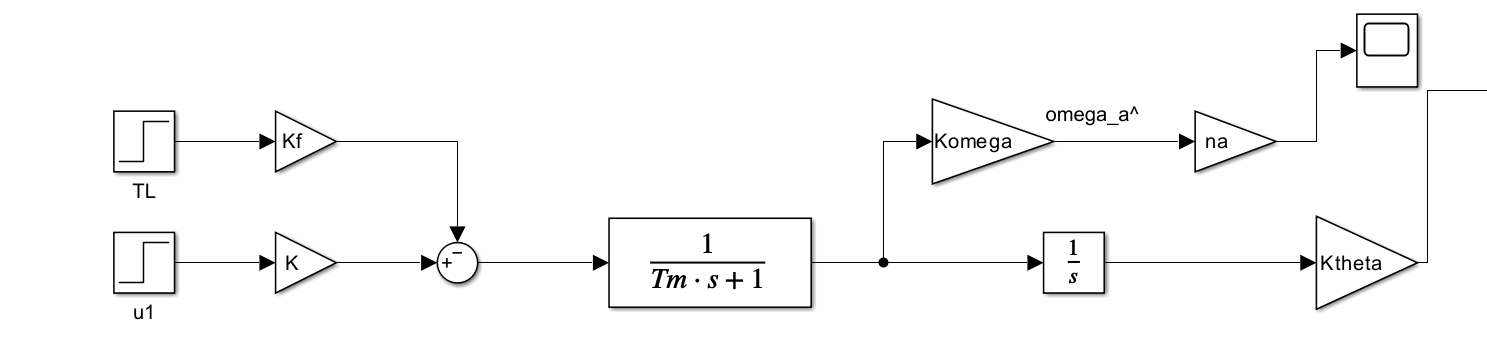

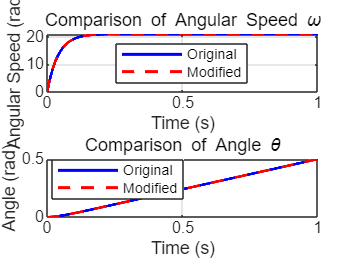


Tc = 0.1*Tc_original;
Te_val = 0.1*Te_original;

simOut = sim(model_name);

time = simOut.tout;
omega_m_s = simOut.omega_m_s{1}.Values.Data;
theta_a_s = simOut.theta_a_s{1}.Values.Data;
omega_a_s = simOut.omega_a_s{1}.Values.Data;
theta_a_ss = simOut.theta_a_ss{1}.Values.Data;

figure;

% 子图1：角速度 ω 比较
subplot(2, 1, 1);
plot(time, omega_m_s, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Original');
hold on;
plot(time, omega_a_s, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Modified');
xlabel('Time (s)');
ylabel('Angular Speed (rad/s)');
title('Comparison of Angular Speed \omega');
legend('Location', 'best');
grid on;
hold off;

% 子图2：角度 θ 比较
subplot(2, 1, 2);
plot(time, theta_a_s, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Original');
hold on;
plot(time, theta_a_ss, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Modified');
xlabel('Time (s)');
ylabel('Angle (rad)');
title('Comparison of Angle \theta');
legend('Location', 'best');
grid on;
hold off;

**Comment:**

*I can see that The angular velocity and angular images of the two models coincide almost perfectly.*

## 状态空间表示


% 完整模型状态空间表示
% 状态变量: [ia; ωm; θa; va]
A_full = [-1/Te_val, -ke*kd/Te_val, 0, kd/Te_val;
          km/J_sigma, 0, 0, 0;
          0, 1/na, 0, 0;
          0, 0, 0, -1/Tc];

B_full = [0; 0; 0; kc/Tc];

C_full = [Kd, 0, 0, 0;    % 电流测量
          0, Komega, 0, 0; % 转速测量
          0, 0, Ktheta, 0; % 角度测量
          0, 0, 0, Kc];    % 电压测量

D_full = [0; 0; 0; 0];

% 简化模型状态空间表示
% 状态变量: [ωa]
A_simple = -1/Tm;
B_simple = [k_simplified/Tm, -kf/Tm];
C_simple = [Komega; Ktheta/Tm];  % 转速和角度测量
D_simple = [0 0; 0 0];

disp('完整模型状态空间表示:');

完整模型状态空间表示:


disp('A矩阵:'); disp(A_full);

A矩阵:
   1.0e+03 *

   -3.3333   -0.3370         0    3.9216
    0.2451         0         0         0
         0    0.0000         0         0
         0         0         0   -1.6667



disp('B矩阵:'); disp(B_full);

B矩阵:
           0
           0
           0
        6000



disp('C矩阵:'); disp(C_full);

C矩阵:
    0.1000         0         0         0
         0    0.1000         0         0
         0         0    0.1000         0
         0         0         0    0.1000



disp('D矩阵:'); disp(D_full);

D矩阵:
     0
     0
     0
     0




disp('简化模型状态空间表示:');

简化模型状态空间表示:


disp('A矩阵:'); disp(A_simple);

A矩阵:
  -24.7843



disp('B矩阵:'); disp(B_simple);

B矩阵:
   25.9541   -1.7470



disp('C矩阵:'); disp(C_simple);

C矩阵:
    0.1000
    2.4784



disp('D矩阵:'); disp(D_simple);

D矩阵:
     0     0
     0     0

